## Matlab code for generateing main figs in the following paper:

[Single cell transcriptomics of human epidermis identifies basal stem cell transition states](https://www.nature.com/articles/s41467-020-18075-7), S. Wang, M. Drummond, C.Guerrero-Juarez, E.Tarapore, A.MacLean, A. Stabell, S. Wu, G. Gutierrez, B. That, C. Benavente, Q. Nie & S. X. Atwood, Nature Communications, 2020.

- All the results are generated by applying SoptSC to the single-cell rna-seq data, for detailed useage of SoptSC, please refer to

- [https://github.com/WangShuxiong/SoptSC](https://github.com/WangShuxiong/SoptSC)

- Some figures are generated using custermized code below

% Add tools into matlab path
addpath('Data');
addpath('NNDSVD');
addpath('symnmf2');
addpath('EE');
addpath('vinlinplot');
addpath('scTools');
addpath('scTools/graphViz2Mat1');
addpath('Cell_Cell_Communication');
addpath('gephi');
addpath('Results');

#### Step 1 (Required)

Load data

%% Step 1: load data
load Data_Figure1_and_Figure2.mat;

% Set the folder to save all figures
folder = 'Results\Fig1_2';
folder1 = 'Results/Fig1_2';

#### Step 2: Generating all mian figures 1 & 2 in the paper

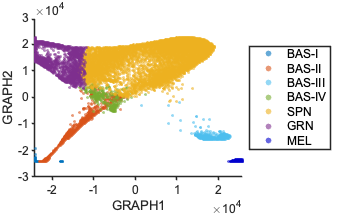

%% Fig1B
figname = 'Fig1B';
method = 'GRAPH';
No_cluster = Data_Figure1_and_Figure2.No_cluster;
cluster_order = 1:No_cluster; % cluster orders for plots
plot_cluster(Data_Figure1_and_Figure2.latent,Data_Figure1_and_Figure2.cluster_label,Data_Figure1_and_Figure2.No_cluster,...
    Data_Figure1_and_Figure2.cluster_legend,folder,cluster_order,method,figname,Data_Figure1_and_Figure2.cluster_color);

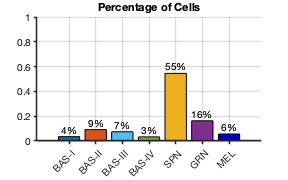

%% Fig1B: percentage of cells in each cluster
figname = 'Fig1B';
cluster_order = 1:No_cluster; % cluster orders for plots
Plot_No_of_Cells(Data_Figure1_and_Figure2.cluster_label,Data_Figure1_and_Figure2.cluster_legend,folder,cluster_order,...
    Data_Figure1_and_Figure2.cluster_color,figname);

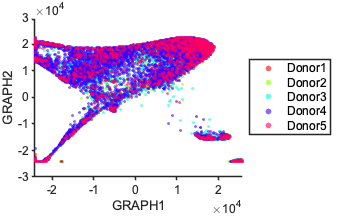

%% Fig1C
figname = 'Batch_ID';
method = 'GRAPH';        % set method as 'pca' or 'tsne'
No_cluster1 = max(Data_Figure1_and_Figure2.batch_id);
batch_order = 1:No_cluster1;
plot_cluster(Data_Figure1_and_Figure2.latent,Data_Figure1_and_Figure2.batch_id,No_cluster1,Data_Figure1_and_Figure2.batch_legend,...
    folder,batch_order,method,figname,Data_Figure1_and_Figure2.cluster_batch_color);

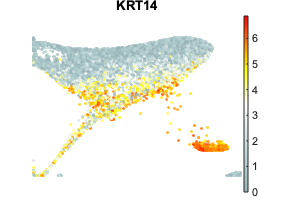

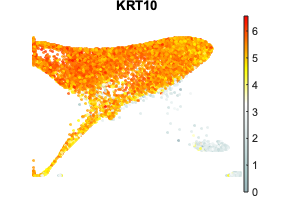

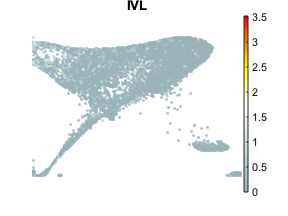

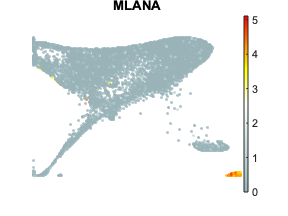

%% Fig1E, feature plots
Marker = {'KRT14', 'KRT10','IVL', 'MLANA', };
plot_feature(Data_Figure1_and_Figure2.data,Marker,Data_Figure1_and_Figure2.allgenes,Data_Figure1_and_Figure2.latent,folder);

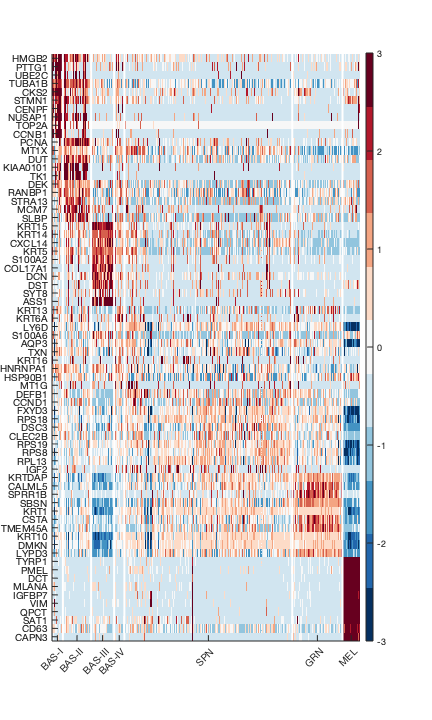

%% Fig2A, gene-cell heatmap of top markers
figname = 'Fig2A';
topn = 10;
GC_htmp_DE_lgd(Data_Figure1_and_Figure2.data,Data_Figure1_and_Figure2.allgenes,Data_Figure1_and_Figure2.cluster_label,...
    topn,Data_Figure1_and_Figure2.cluster_legend,figname,folder,folder1);

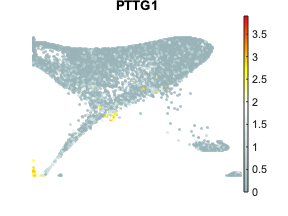

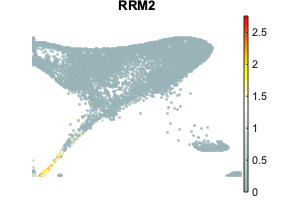

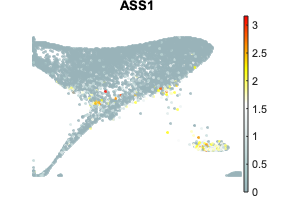

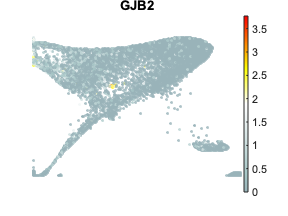

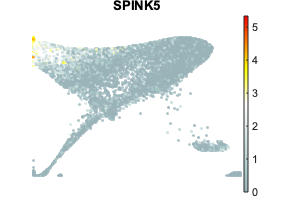

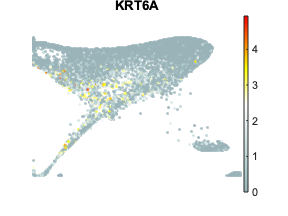

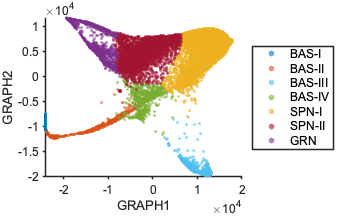

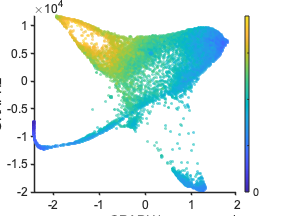

Unrecognized function or variable 'allgenes'.

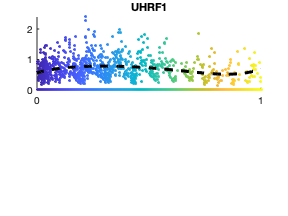

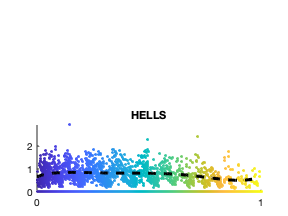

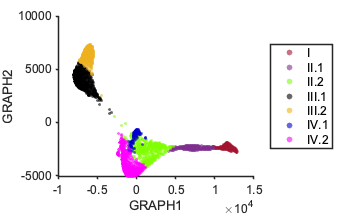

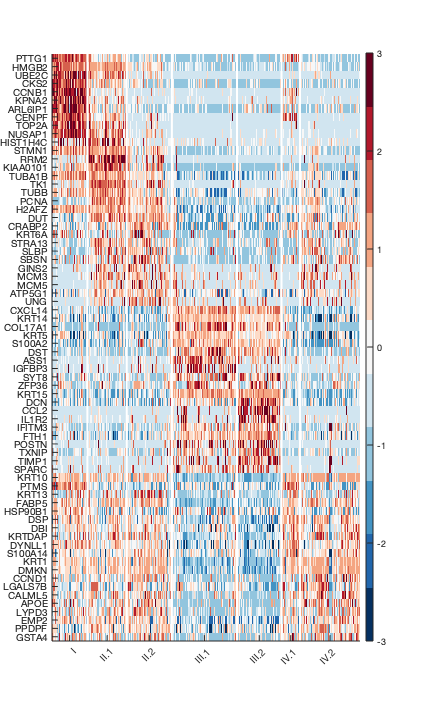

nComponents = 1

Root cluster candidates:
     1     5

Inferred root cell is:


root_cell = 1

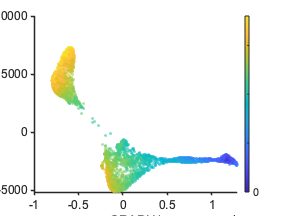

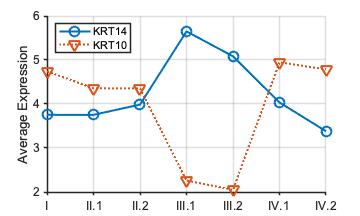

%% Fig2D, feature plots
Marker = {'PTTG1', 'RRM2','ASS1','GJB2','SPINK5','KRT6A'};
plot_feature(Data_Figure1_and_Figure2.data,Marker,Data_Figure1_and_Figure2.allgenes,Data_Figure1_and_Figure2.latent,folder);